# Ziegler-Nichols 2 (Stabilit?tsgrenze) und Phasenreserve

*Gesundheitsmechatronik - Regelungstechnik, Dr. Pierre Elbischger, 23.5.2017*

In dieser ?bung soll eine F?hrungsgr??enregelung, f?r eine vorgegebene PTn-Regelstrecke realisiert werden. Die Reglereinstellung soll mittels Phasenrandvorgabe sowie durch eine Einstellung nach Ziegler-Nichols erfolgen.

clear, close all, clc

## Modellierung der Regelstrecke

Nachfolgend wird die zu untersuchende PT4-Strecke modelliert und deren Sprung- und Frequenzantwort werden dargestellt.

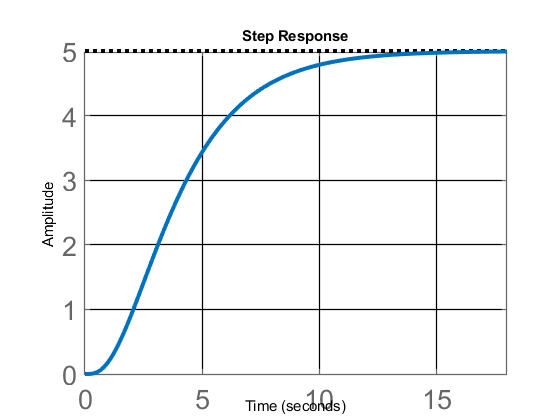

s = tf('s'); % komplexe Frequenz
T1 = 2.4; T2 = 1.2; T3 = 0.6; T4 = .1; Ks = 5;
Gs = Ks/(1+s*T1)*1/(1+s*T2)*1/(1+s*T3)*1/(1+s*T4);

figure, step(Gs), grid on
set(findall(gcf,'Type','Line'),'LineWidth',3)
vH = findobj(gcf,'type','axes');
set(vH, 'LineWidth', 1, 'FontSize', 20, 'GridColor', [0 0 0 ], 'GridAlpha', 1, 'MinorGridColor', [0 0 0 ], 'MinorGridAlpha', 0.8)

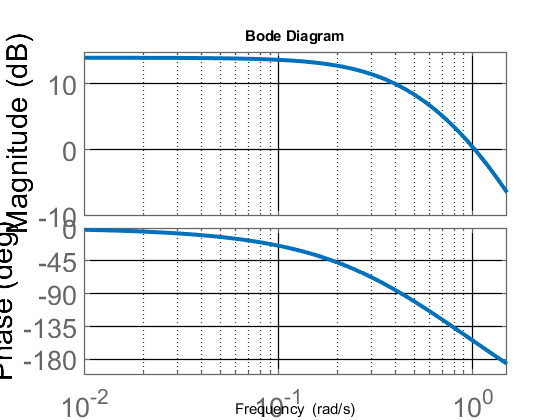


figure, bode(Gs, {1e-2 1.5}), grid on
ylim([-200 0])
set(findall(gcf,'Type','Line'),'LineWidth',3)
vH = findobj(gcf,'type','axes');
set(vH, 'LineWidth', 1, 'FontSize', 20, 'GridColor', [0 0 0 ], 'GridAlpha', 1, 'MinorGridColor', [0 0 0 ], 'MinorGridAlpha', 0.8)

## KONSTRUKTION AUS DEM FREQUENZGANG

Die Konstruktion erfolg auf Papier im bereitgestellten Frequenzgang der Regelstrecke. Die Lehrkraft zeigt die Konstruktion am Beamer vor. Die exakten Werte sind mit Schlussrechnungen zu ermitteln.

%<ToDo />

**Ermitteln sie die unterschiedlichen Ma?st?be aus dem Diagramm.**

%<ToDo />
dBPerMm = 10/50;
degPerMm = 180/100,

degPerMm = 1.8000

mmPerDec = 74;

**Kritische Verst?rkung des P-Reglers**: Die Regelstrecke wird mit einem P-Regler geregelt. Ermitteln sie den Proportionalit?tsbeiwert Kp_krit des P-Reglers (dB und Faktor), bei welchem sich der Regelkreis an der Stabilit?tsgrenze befindet, d.h. als Oszillator arbeitet (arg(G0)=180? bei `G0`=1).

%<ToDo />
Kp_krit_mm = 25;
Kp_krit_dB = dBPerMm * Kp_krit_mm;
Kp_krit = 10 ^(Kp_krit_dB / 20)

Kp_krit = 1.7783

**Periodendauer bei krititischer Verst?rkung**: Berechnen sie die zu erwartende Periodendauer bei der kritischen Verst?rkung Kp_krit.

%<ToDo />
n = 0; %Dekade
w_krit_mm = 10;
w_krit = 10^(n +w_krit_mm/mmPerDec);
f_krit = w_krit/(2*pi);
T_krit = 1/f_krit;

% *Welchen Phasen- und Amplitudenrand hat der Regelkreis bei Kp_krit?*

%<ToDo />

## SIMULATION DES REGELKREISES

Die aus dem Frequenzgang konstruierten Werte sollen nun mit Simulationsergebnissen verglichen werdern. Verwenden sie den pidTuner() um den Regelkreis zu simulieren und stellen sie den F?hrungsgr??ensprung sowie die Schleifenverst?rkung nebeneinander dar. Blenden sie die Tabelle mit der Parameter?bersiche ein und zeigen sie den PR sowie den AR im Frequenzgang an. Verwenden sie das Snipping-Tool von Windows, um die Simulationsergebnisse in eine ppt-Datei zu ?bertragen.

**Ziegler-Nichols (Stabilit?tsgrenze): Bestimmung der kritischen Verst?rkung**: Stellen sie den P-Regler mit dem pidTuner(Gs, 'p') nun auf die Stabilit?sgrenze ein. Es soll der F?hrungsgr??ensprung sowie der Frequenzgang des offenen Regelkreises dargestellt werden. Vergleichen sie die so ermittelte kritische Verst?rkung und die resultierende Periodendauer der Regelgr??e mit den zuvor berechneten Werten.

%<ToDo />

<<..% 

## Ermittlung der Regelparameter nach Ziegler-Nichols 2 (ZN2)

Berechnung der Reglerparameter f?r einen PI-Regler. Die notwendigen Formeln wurden aus der Tabelle im Skriptum entnommen.

%<ToDo />

## Reglereinstellung nach Phasenrandvorgabe

Konstruieren sie aus dem Frequenzgang die Einstellung eines P-Reglers f?r 60? Phasenrand. Simulieren sie das Verhalten des Regelkreises mit dem pidTuner().

%<ToDo />

## Reglereinstellung mit dem PID-Tuner

Verwenden sie nun den pidTuner(), um den Regelkreis mit einem P-Regler auf 30? und 120? Phasenreserve einzustellen.

%<ToDo />